number_points = 1601;
gain_prof_amp = zeros(number_points,1);
gain_prof_phase = zeros(number_points,1);
freqs = linspace(5.5e9,5.63e9,number_points);
gain_prof_freq = freqs;
kappa_ext = 1.5e6;
kappa_int_0 = .4e6;
kappa_int_1 = .4e6;
omega_0 = 5.55e9;
sigma_0 = 0.5e6;
sigma_1 = 0.5e6;
delta = freqs - omega_0;
omega_1 = 5.6e9;
p_omega_0 = .85;
halfway_freq = (omega_1 + omega_0)/2;
phase_offset_second_res = 0;
 
kappa_tot = kappa_int_0 + kappa_ext;

[s11_qp_omega_0_real, s11_qp_omega_0_imag] = q_circle_with_freq_flucs(freqs,kappa_int_0,kappa_ext,omega_0,sigma_0);
[s11_qp_omega_1_real, s11_qp_omega_1_imag] = q_circle_with_freq_flucs(freqs,kappa_int_1,kappa_ext,omega_1,sigma_1);

[s11_qp_omega_1_lin_mag, s11_qp_omega_1_phase_radians] = extract_lin_mag_phase_from_real_imag(s11_qp_omega_1_real, s11_qp_omega_1_imag, freqs);
[s11_qp_omega_1_log_mag, s11_qp_omega_1_phase_degs] = extract_log_mag_phase_degs(s11_qp_omega_1_lin_mag, s11_qp_omega_1_phase_radians);
s11_qp_omega_1_phase_degs = s11_qp_omega_1_phase_degs + phase_offset_second_res;
[s11_qp_omega_1_lin_mag, s11_qp_omega_1_phase_radians] = extract_lin_mag_and_phase_radians(freqs, s11_qp_omega_1_log_mag, s11_qp_omega_1_phase_degs);
[s11_qp_omega_1_real, s11_qp_omega_1_imag] = extract_real_imag(freqs, s11_qp_omega_1_lin_mag, s11_qp_omega_1_phase_radians);

s11_qp_test_real = p_omega_0 * s11_qp_omega_0_real + (1-p_omega_0)*s11_qp_omega_1_real;
s11_qp_test_imag = p_omega_0 * s11_qp_omega_0_imag + (1-p_omega_0)*s11_qp_omega_1_imag;
[data_lin_mag_qp, data_phase_radians_qp] = extract_lin_mag_phase_from_real_imag(s11_qp_test_real,s11_qp_test_imag,freqs);
[data_log_mag_qp, data_phase_degs_qp] = extract_log_mag_phase_degs(data_lin_mag_qp, data_phase_radians_qp);

[err_with_flucs_omega_0,res_freq_fit_with_flucs_omega_0,gamma_int_fit_with_flucs_omega_0,gamma_ext_fit_with_flucs_omega_0,sigma_fit_with_flucs_omega_0,...
    data_real_with_flucs_omega_0,data_imag_with_flucs_omega_0,theory_real_with_flucs_omega_0,theory_imag_with_flucs_omega_0]=...
    fit_q_circle_with_freq_flucs(data_log_mag_qp(freqs<halfway_freq),data_phase_degs_qp(freqs<halfway_freq),freqs(freqs<halfway_freq),1e6,1e6,1e6);
[theory_lin_mag_with_flucs_omega_0, theory_phase_radians_with_flucs_omega_0] = extract_lin_mag_phase_from_real_imag(theory_real_with_flucs_omega_0, theory_imag_with_flucs_omega_0, freqs(freqs<halfway_freq));
[theory_log_mag_with_flucs_omega_0, theory_phase_degs_with_flucs_omega_0] = extract_log_mag_phase_degs(theory_lin_mag_with_flucs_omega_0, theory_phase_radians_with_flucs_omega_0);

% [err_with_flucs_omega_1,res_freq_fit_with_flucs_omega_1,gamma_int_fit_with_flucs_omega_1,gamma_ext_fit_with_flucs_omega_1,sigma_fit_with_flucs_omega_1,...
%     data_real_with_flucs_omega_1,data_imag_with_flucs_omega_1,theory_real_with_flucs_omega_1,theory_imag_with_flucs_omega_1]=...
%     fit_q_circle_with_freq_flucs(data_log_mag_qp(freqs>halfway_freq),data_phase_degs_qp(freqs>halfway_freq)-phase_offset_second_res,freqs(freqs>halfway_freq),1e6,1e6,1e6);
[err_with_flucs_omega_1,res_freq_fit_with_flucs_omega_1,gamma_int_fit_with_flucs_omega_1,gamma_ext_fit_with_flucs_omega_1,sigma_fit_with_flucs_omega_1,...
    data_real_with_flucs_omega_1,data_imag_with_flucs_omega_1,theory_real_with_flucs_omega_1,theory_imag_with_flucs_omega_1]=...
    fit_q_circle_with_freq_flucs(data_log_mag_qp(freqs>halfway_freq),data_phase_degs_qp(freqs>halfway_freq),freqs(freqs>halfway_freq),1e6,1e6,1e6);
[theory_lin_mag_with_flucs_omega_1, theory_phase_radians_with_flucs_omega_1] = extract_lin_mag_phase_from_real_imag(theory_real_with_flucs_omega_1, theory_imag_with_flucs_omega_1, freqs(freqs>halfway_freq));
[theory_log_mag_with_flucs_omega_1, theory_phase_degs_with_flucs_omega_1] = extract_log_mag_phase_degs(theory_lin_mag_with_flucs_omega_1, theory_phase_radians_with_flucs_omega_1);
% theory_phase_degs_with_flucs_omega_1 = theory_phase_degs_with_flucs_omega_1 + phase_offset_second_res;

[err_angle_omega_0,res_freq_fit_angle_omega_0,gamma_int_fit_angle_omega_0,gamma_ext_fit_angle_omega_0,sigma_fit_angle_omega_0,angle_fit_angle_omega_0,...
    data_real_angle_omega_0,data_imag_angle_omega_0,theory_real_angle_omega_0,theory_imag_angle_omega_0]=...
    fit_q_circle_with_freq_flucs_and_angle(data_log_mag_qp(freqs<halfway_freq),data_phase_degs_qp(freqs<halfway_freq),freqs(freqs<halfway_freq),1e6,1e6,1e6);
[theory_lin_mag_angle_omega_0, theory_phase_radians_angle_omega_0] = extract_lin_mag_phase_from_real_imag(theory_real_angle_omega_0, theory_imag_angle_omega_0, freqs(freqs<halfway_freq));
[theory_log_mag_angle_omega_0, theory_phase_degs_angle_omega_0] = extract_log_mag_phase_degs(theory_lin_mag_angle_omega_0, theory_phase_radians_angle_omega_0);

% [err_angle_omega_1,res_freq_fit_angle_omega_1,gamma_int_fit_angle_omega_1,gamma_ext_fit_angle_omega_1,sigma_fit_angle_omega_1,angle_fit_angle_omega_1,...
%     data_real_angle_omega_1,data_imag_angle_omega_1,theory_real_angle_omega_1,theory_imag_angle_omega_1]=...
%     fit_q_circle_with_freq_flucs_and_angle(data_log_mag_qp(freqs>halfway_freq),data_phase_degs_qp(freqs>halfway_freq) -phase_offset_second_res,freqs(freqs>halfway_freq),2.5e6,.5e6,1e6);
[err_angle_omega_1,res_freq_fit_angle_omega_1,gamma_int_fit_angle_omega_1,gamma_ext_fit_angle_omega_1,sigma_fit_angle_omega_1,angle_fit_angle_omega_1,...
    data_real_angle_omega_1,data_imag_angle_omega_1,theory_real_angle_omega_1,theory_imag_angle_omega_1]=...
    fit_q_circle_with_freq_flucs_and_angle(data_log_mag_qp(freqs>halfway_freq),data_phase_degs_qp(freqs>halfway_freq),freqs(freqs>halfway_freq),2.5e6,.5e6,1e6);
[theory_lin_mag_angle_omega_1, theory_phase_radians_angle_omega_1] = extract_lin_mag_phase_from_real_imag(theory_real_angle_omega_1, theory_imag_angle_omega_1, freqs(freqs>halfway_freq));
[theory_log_mag_angle_omega_1, theory_phase_degs_angle_omega_1] = extract_log_mag_phase_degs(theory_lin_mag_angle_omega_1, theory_phase_radians_angle_omega_1);
% theory_phase_degs_angle_omega_1 = theory_phase_degs_angle_omega_1 + phase_offset_second_res;

[s11_original_real_omega_0, s11_original_imag_omega_0]=q_circle_with_freq_flucs(freqs,kappa_int_0,kappa_ext,omega_0,sigma_0);
[data_lin_mag_original_omega_0, data_phase_radians_original_omega_0] = extract_lin_mag_phase_from_real_imag(s11_original_real_omega_0,s11_original_imag_omega_0,freqs);
[data_log_mag_original_omega_0, data_phase_degs_original_omega_0] = extract_log_mag_phase_degs(data_lin_mag_original_omega_0, data_phase_radians_original_omega_0);

[s11_original_real_omega_1, s11_original_imag_omega_1]=q_circle_with_freq_flucs(freqs,kappa_int_1,kappa_ext,omega_1,sigma_1);
[data_lin_mag_original_omega_1, data_phase_radians_original_omega_1] = extract_lin_mag_phase_from_real_imag(s11_original_real_omega_1,s11_original_imag_omega_1,freqs);
[data_log_mag_original_omega_1, data_phase_degs_original_omega_1] = extract_log_mag_phase_degs(data_lin_mag_original_omega_1, data_phase_radians_original_omega_1);

[err_with_flucs_original_omega_0,res_freq_fit_with_flucs_original_omega_0,gamma_int_fit_with_flucs_original_omega_0,...
    gamma_ext_fit_with_flucs_original_omega_0,sigma_fit_with_flucs_original_omega_0, data_real_with_flucs_original_omega_0,...
    data_imag_with_flucs_original_omega_0,theory_real_with_flucs_original_omega_0,theory_imag_with_flucs_original_omega_0]=...
    fit_q_circle_with_freq_flucs(data_log_mag_original_omega_0,data_phase_degs_original_omega_0,freqs,1e6,1e6,1e6);
[theory_lin_mag_with_flucs_original_omega_0, theory_phase_radians_with_flucs_original_omega_0] = ...
    extract_lin_mag_phase_from_real_imag(theory_real_with_flucs_original_omega_0, theory_imag_with_flucs_original_omega_0, freqs);
[theory_log_mag_with_flucs_original_omega_0, theory_phase_degs_with_flucs_original_omega_0] =...
    extract_log_mag_phase_degs(theory_lin_mag_with_flucs_original_omega_0, theory_phase_radians_with_flucs_original_omega_0);

[err_with_flucs_original_omega_1,res_freq_fit_with_flucs_original_omega_1,gamma_int_fit_with_flucs_original_omega_1,...
    gamma_ext_fit_with_flucs_original_omega_1,sigma_fit_with_flucs_original_omega_1, data_real_with_flucs_original_omega_1,...
    data_imag_with_flucs_original_omega_1,theory_real_with_flucs_original_omega_1,theory_imag_with_flucs_original_omega_1]=...
    fit_q_circle_with_freq_flucs(data_log_mag_original_omega_1,data_phase_degs_original_omega_1,freqs,1e6,1e6,1e6);
[theory_lin_mag_with_flucs_original_omega_1, theory_phase_radians_with_flucs_original_omega_1] = ...
    extract_lin_mag_phase_from_real_imag(theory_real_with_flucs_original_omega_1, theory_imag_with_flucs_original_omega_1, freqs);
[theory_log_mag_with_flucs_original_omega_1, theory_phase_degs_with_flucs_original_omega_1] =...
    extract_log_mag_phase_degs(theory_lin_mag_with_flucs_original_omega_1, theory_phase_radians_with_flucs_original_omega_1);

[err_angle_original_omega_0,res_freq_fit_angle_original_omega_0,gamma_int_fit_angle_original_omega_0,gamma_ext_fit_angle_original_omega_0,...
    sigma_fit_angle_original_omega_0,angle_fit_angle_original_omega_0,data_real_angle_original_omega_0,data_imag_angle_original_omega_0,...
    theory_real_angle_original_omega_0,theory_imag_angle_original_omega_0]=...
    fit_q_circle_with_freq_flucs_and_angle(data_log_mag_original_omega_0,data_phase_degs_original_omega_0,freqs,1e6,1e6,1e6);
[theory_lin_mag_angle_original_omega_0, theory_phase_radians_angle_original_omega_0] = ...
    extract_lin_mag_phase_from_real_imag(theory_real_angle_original_omega_0, theory_imag_angle_original_omega_0, freqs);
[theory_log_mag_angle_original_omega_0, theory_phase_degs_angle_original_omega_0] =...
    extract_log_mag_phase_degs(theory_lin_mag_angle_original_omega_0, theory_phase_radians_angle_original_omega_0);

[err_angle_original_omega_1,res_freq_fit_angle_original_omega_1,gamma_int_fit_angle_original_omega_1,gamma_ext_fit_angle_original_omega_1,...
    sigma_fit_angle_original_omega_1,angle_fit_angle_original_omega_1, data_real_angle_original_omega_1,data_imag_angle_original_omega_1,...
    theory_real_angle_original_omega_1,theory_imag_angle_original_omega_1]=...
    fit_q_circle_with_freq_flucs_and_angle(data_log_mag_original_omega_1,data_phase_degs_original_omega_1,freqs,1e6,1e6,1e6);
[theory_lin_mag_angle_original_omega_1, theory_phase_radians_angle_original_omega_1] = ...
    extract_lin_mag_phase_from_real_imag(theory_real_angle_original_omega_1, theory_imag_angle_original_omega_1, freqs);
[theory_log_mag_angle_original_omega_1, theory_phase_degs_angle_original_omega_1] =...
    extract_log_mag_phase_degs(theory_lin_mag_angle_original_omega_1, theory_phase_radians_angle_original_omega_1);

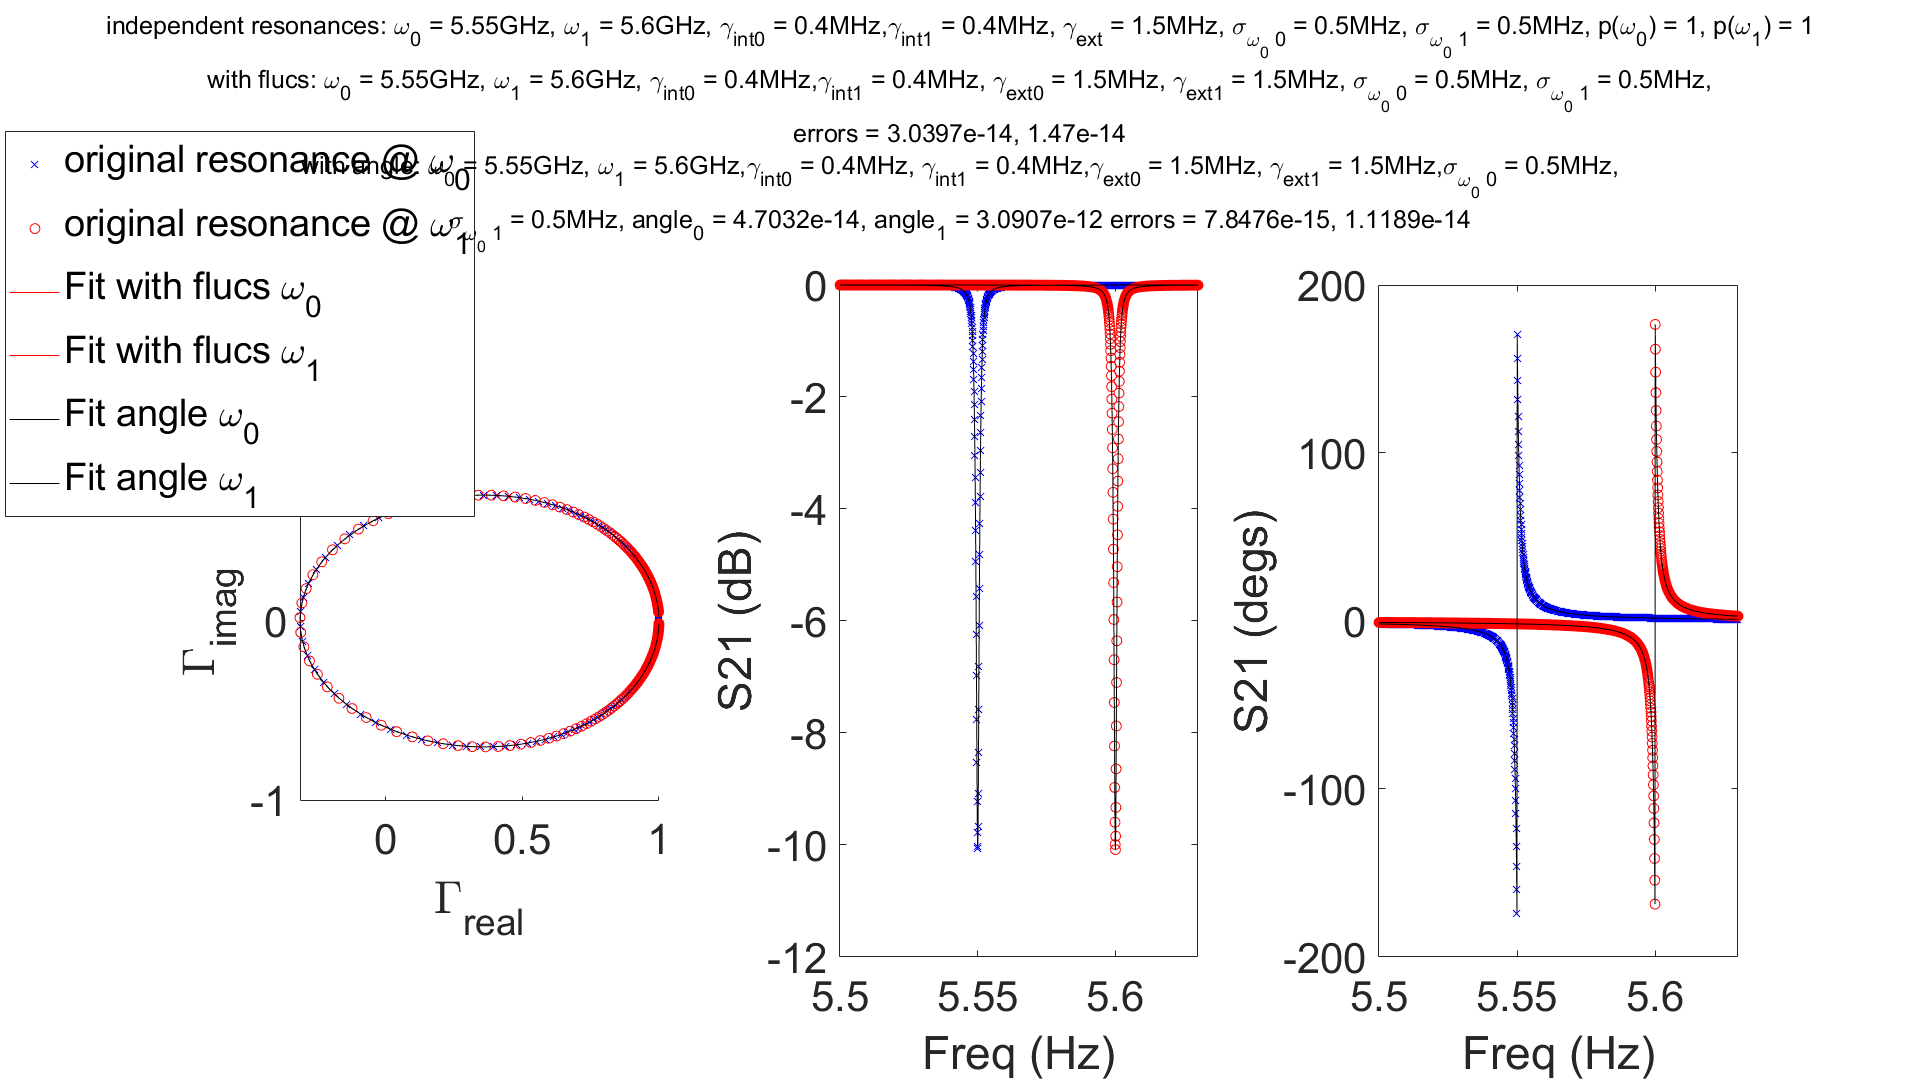

freqs = freqs/1e9;
halfway_freq = halfway_freq/1e9;
figure
sgtitle(['independent resonances: \omega_0 = ' num2str(omega_0/1e9) 'GHz, \omega_1 = ' num2str(omega_1/1e9) 'GHz, \gamma_{int0} = ' num2str(kappa_int_0/1e6) 'MHz,'...
    '\gamma_{int1} = ' num2str(kappa_int_1/1e6) 'MHz, \gamma_{ext} = ' num2str(kappa_ext/1e6) 'MHz, \sigma_{\omega_0 0} = ' num2str(sigma_0/1e6) 'MHz,'...
    ' \sigma_{\omega_0 1} = ' num2str(sigma_1/1e6) 'MHz, p(\omega_0) = 1, p(\omega_1) = 1' 13 10 'with flucs: \omega_0 = ' num2str(res_freq_fit_with_flucs_original_omega_0/1e9)...
    'GHz, \omega_1 = ' num2str(res_freq_fit_with_flucs_original_omega_1/1e9) 'GHz, \gamma_{int0} = ' num2str(gamma_int_fit_with_flucs_original_omega_0/1e6) 'MHz,'...
    '\gamma_{int1} = ' num2str(gamma_int_fit_with_flucs_original_omega_1/1e6) 'MHz, \gamma_{ext0} = ' num2str(gamma_ext_fit_with_flucs_original_omega_0/1e6) 'MHz, \gamma_{ext1} = '...
    num2str(gamma_ext_fit_with_flucs_original_omega_1/1e6) 'MHz, \sigma_{\omega_0 0} = ' num2str(sigma_fit_with_flucs_original_omega_0/1e6) 'MHz,'...
    ' \sigma_{\omega_0 1} = ' num2str(sigma_fit_with_flucs_original_omega_1/1e6) 'MHz,' 13 10 'errors = ' num2str(err_with_flucs_original_omega_0) ', ' num2str(err_with_flucs_original_omega_1)...
    13 10 'with angle: \omega_0 = ' num2str(res_freq_fit_angle_original_omega_0/1e9) 'GHz, \omega_1 = ' num2str(res_freq_fit_angle_original_omega_1/1e9) 'GHz,'...
    '\gamma_{int0} = ' num2str(gamma_int_fit_angle_original_omega_0/1e6) 'MHz, \gamma_{int1} = ' num2str(gamma_int_fit_angle_original_omega_1/1e6) 'MHz,'...
    '\gamma_{ext0} = ' num2str(gamma_ext_fit_angle_original_omega_0/1e6) 'MHz, \gamma_{ext1} = ' num2str(gamma_ext_fit_angle_original_omega_1/1e6) 'MHz,'...
    '\sigma_{\omega_0 0} = ' num2str(sigma_fit_angle_original_omega_0/1e6) 'MHz,' 13 10 '\sigma_{\omega_0 1} = ' num2str(sigma_fit_angle_original_omega_1/1e6)...
    'MHz, angle_0 = ' num2str(angle_fit_angle_original_omega_0) ', angle_1 = ' num2str(angle_fit_angle_original_omega_1) ' errors = ' num2str(err_angle_original_omega_0) ', '...
    num2str(err_angle_original_omega_1)])
subplot(1,3,1)
scatter(s11_original_real_omega_0,s11_original_imag_omega_0,'xb','DisplayName','original resonance @ \omega_0')
hold on
scatter(s11_original_real_omega_1,s11_original_imag_omega_1,'or','DisplayName','original resonance @ \omega_1')
plot(theory_real_with_flucs_original_omega_1,theory_imag_with_flucs_original_omega_1, 'r', 'DisplayName', 'fit With flucs, \omega_1')
plot(theory_real_with_flucs_original_omega_0,theory_imag_with_flucs_original_omega_0, 'r', 'DisplayName', 'fit With flucs, \omega_0')
plot(theory_real_angle_original_omega_0,theory_imag_angle_original_omega_0, 'k', 'DisplayName', 'fit With angle, \omega_0')
plot(theory_real_angle_original_omega_1,theory_imag_angle_original_omega_1, 'k', 'DisplayName', 'fit With angle, \omega_1')
pbaspect([1 1 1])
xlabel('\Gamma_{real}')
ylabel('\Gamma_{imag}')

subplot(1,3,2)
plot(freqs,data_log_mag_original_omega_0,'xb','DisplayName','original resonance @ \omega_0')
hold on
plot(freqs,data_log_mag_original_omega_1,'or','DisplayName','original resonance @ \omega_1')
plot(freqs, theory_log_mag_with_flucs_original_omega_0,'r', 'DisplayName','Fit with flucs \omega_0')
plot(freqs, theory_log_mag_with_flucs_original_omega_1,'r', 'DisplayName','Fit with flucs \omega_1')
plot(freqs, theory_log_mag_angle_original_omega_0,'k', 'DisplayName','Fit angle \omega_0')
plot(freqs, theory_log_mag_angle_original_omega_1,'k', 'DisplayName','Fit angle \omega_1')
xlabel('Freq (Hz)')
ylabel('S21 (dB)')
legend ('show','Position',[0.075 0.6 0.1 0.2])%'Position',[0.2 0.6 0.1 0.2]

subplot(1,3,3)
plot(freqs,data_phase_degs_original_omega_0,'xb','DisplayName','original resonance @ \omega_0')
hold on
plot(freqs,data_phase_degs_original_omega_1,'or','DisplayName','original resonance @ \omega_1')
plot(freqs, theory_phase_degs_with_flucs_original_omega_0,'r', 'DisplayName','Fit with flucs \omega_0')
plot(freqs, theory_phase_degs_with_flucs_original_omega_1,'r', 'DisplayName','Fit with flucs \omega_1')
plot(freqs, theory_phase_degs_angle_original_omega_0,'k', 'DisplayName','Fit angle \omega_0')
plot(freqs, theory_phase_degs_angle_original_omega_1,'k', 'DisplayName','Fit angle \omega_1')
xlabel('Freq (Hz)')
ylabel('S21 (degs)')

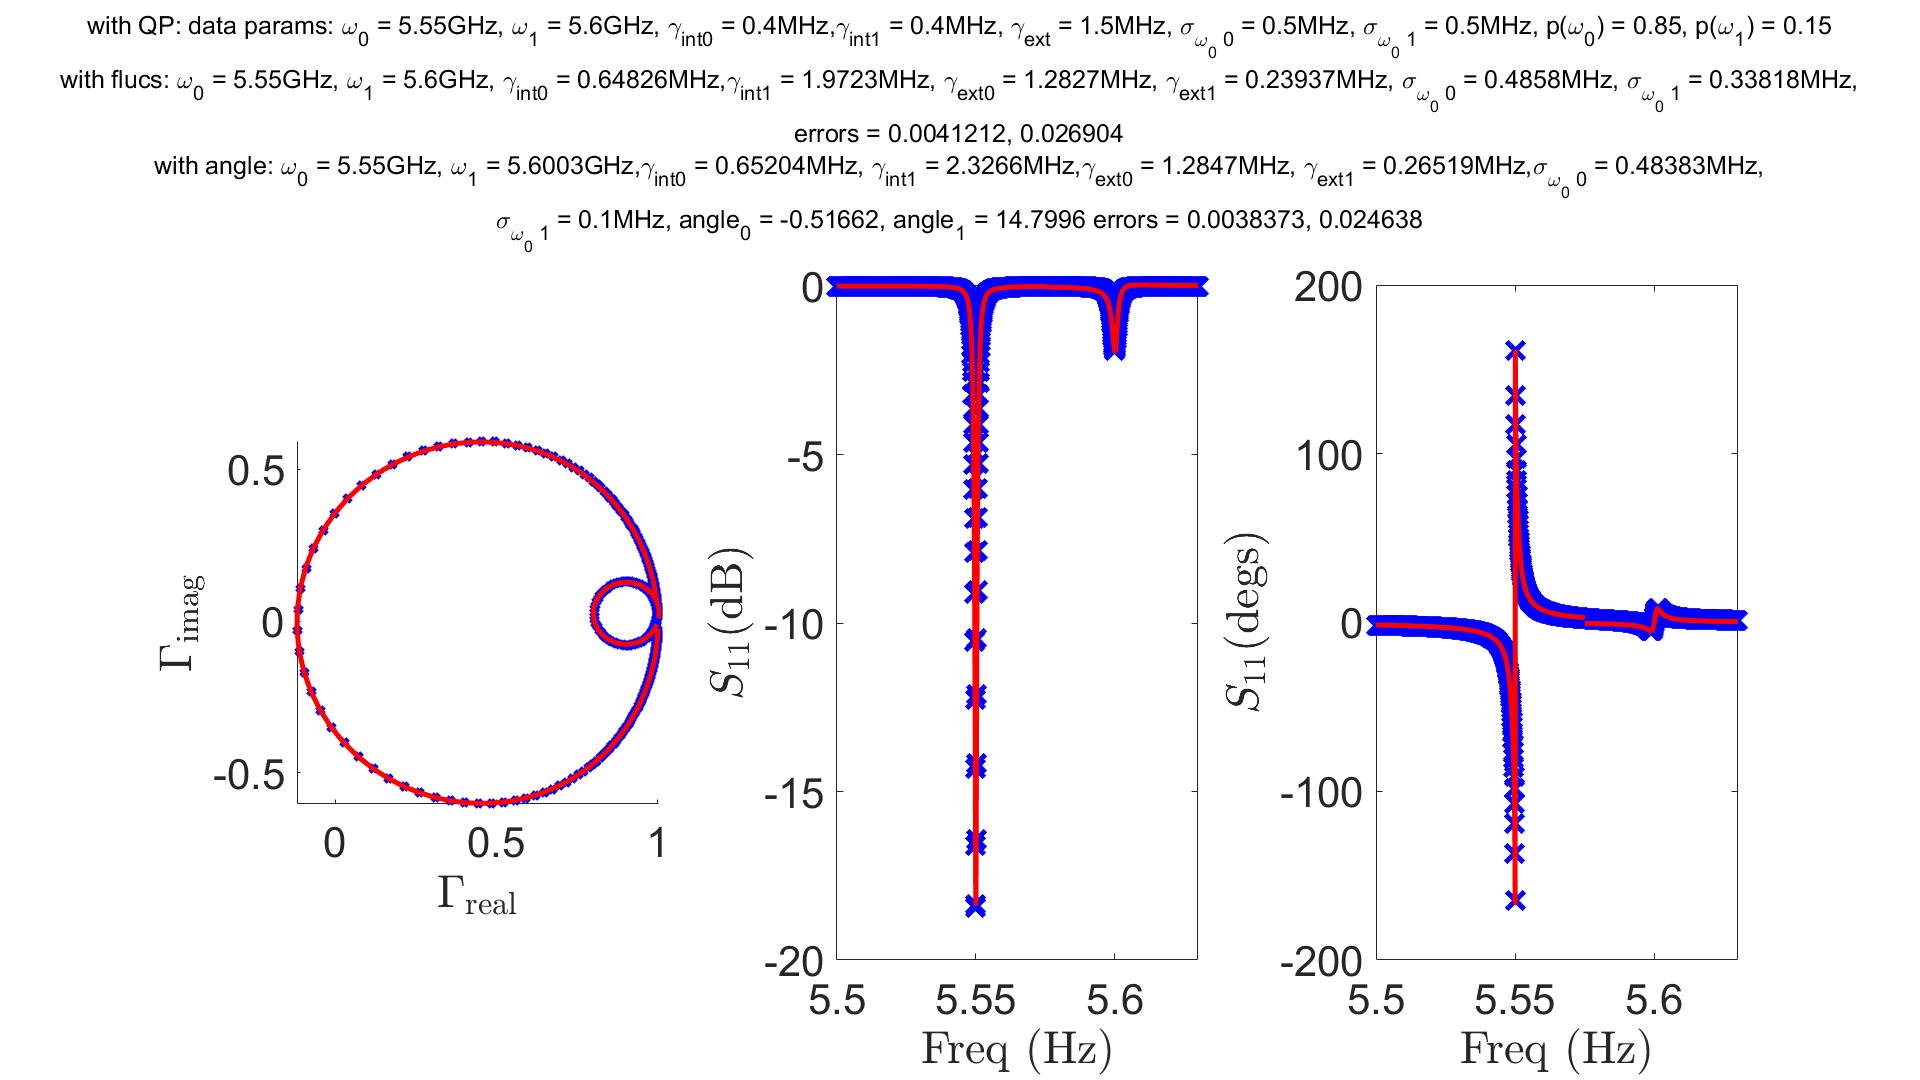

figure
sgtitle(['with QP: data params: \omega_0 = ' num2str(omega_0/1e9) 'GHz, \omega_1 = ' num2str(omega_1/1e9) 'GHz, \gamma_{int0} = ' num2str(kappa_int_0/1e6) 'MHz,'...
    '\gamma_{int1} = ' num2str(kappa_int_1/1e6) 'MHz, \gamma_{ext} = ' num2str(kappa_ext/1e6) 'MHz, \sigma_{\omega_0 0} = ' num2str(sigma_0/1e6) 'MHz,'...
    ' \sigma_{\omega_0 1} = ' num2str(sigma_1/1e6) 'MHz, p(\omega_0) = ' num2str(p_omega_0) ', p(\omega_1) = ' num2str(1-p_omega_0) 13 10 'with flucs: \omega_0 = ' num2str(res_freq_fit_with_flucs_omega_0/1e9)...
    'GHz, \omega_1 = ' num2str(res_freq_fit_with_flucs_omega_1/1e9) 'GHz, \gamma_{int0} = ' num2str(gamma_int_fit_with_flucs_omega_0/1e6) 'MHz,'...
    '\gamma_{int1} = ' num2str(gamma_int_fit_with_flucs_omega_1/1e6) 'MHz, \gamma_{ext0} = ' num2str(gamma_ext_fit_with_flucs_omega_0/1e6) 'MHz, \gamma_{ext1} = '...
    num2str(gamma_ext_fit_with_flucs_omega_1/1e6) 'MHz, \sigma_{\omega_0 0} = ' num2str(sigma_fit_with_flucs_omega_0/1e6) 'MHz,'...
    ' \sigma_{\omega_0 1} = ' num2str(sigma_fit_with_flucs_omega_1/1e6) 'MHz,' 13 10 'errors = ' num2str(err_with_flucs_omega_0) ', ' num2str(err_with_flucs_omega_1)...
    13 10 'with angle: \omega_0 = ' num2str(res_freq_fit_angle_omega_0/1e9) 'GHz, \omega_1 = ' num2str(res_freq_fit_angle_omega_1/1e9) 'GHz,'...
    '\gamma_{int0} = ' num2str(gamma_int_fit_angle_omega_0/1e6) 'MHz, \gamma_{int1} = ' num2str(gamma_int_fit_angle_omega_1/1e6) 'MHz,'...
    '\gamma_{ext0} = ' num2str(gamma_ext_fit_angle_omega_0/1e6) 'MHz, \gamma_{ext1} = ' num2str(gamma_ext_fit_angle_omega_1/1e6) 'MHz,'...
    '\sigma_{\omega_0 0} = ' num2str(sigma_fit_angle_omega_0/1e6) 'MHz,' 13 10 '\sigma_{\omega_0 1} = ' num2str(sigma_fit_angle_omega_1/1e6)...
    'MHz, angle_0 = ' num2str(angle_fit_angle_omega_0) ', angle_1 = ' num2str(angle_fit_angle_omega_1) ' errors = ' num2str(err_angle_omega_0) ', '...
    num2str(err_angle_omega_1)])
subplot(1,3,1)
scatter(s11_qp_test_real,s11_qp_test_imag,'xb', 'linewidth', 3, 'DisplayName','with QP')
hold on
% plot(theory_real_with_flucs_omega_1,theory_imag_with_flucs_omega_1, 'r', 'linewidth',3,'DisplayName', 'With flucs, \omega_1')
% plot(theory_real_with_flucs_omega_0,theory_imag_with_flucs_omega_0, 'r', 'linewidth',3,'DisplayName', 'With flucs, \omega_0')
plot(theory_real_angle_omega_0,theory_imag_angle_omega_0, 'r', 'linewidth',3,'DisplayName', 'With angle, \omega_0')
plot(theory_real_angle_omega_1,theory_imag_angle_omega_1, 'r', 'linewidth',3,'DisplayName', 'With angle, \omega_1')
xlabel('$\Gamma_{\mathrm{real}}$','interpreter','latex','Fontsize', 48)
ylabel('$\Gamma_{\mathrm{imag}}$','interpreter','latex','Fontsize', 48)
pbaspect([1 1 1])
    
subplot(1,3,2)
plot(freqs,data_log_mag_qp,'xb','markersize', 15, 'linewidth', 3, 'DisplayName','"data" resonances @ \omega_0 and \omega_1')
hold on
% plot(freqs(freqs<halfway_freq), theory_log_mag_with_flucs_omega_0,'r', 'linewidth',3,'DisplayName','Fit with flucs \omega_0')
% plot(freqs(freqs>halfway_freq), theory_log_mag_with_flucs_omega_1,'r', 'linewidth',3,'DisplayName','Fit with flucs \omega_1')
plot(freqs(freqs<halfway_freq), theory_log_mag_angle_omega_0,'r', 'linewidth',3,'DisplayName','Fit angle \omega_0')
plot(freqs(freqs>halfway_freq), theory_log_mag_angle_omega_1,'r', 'linewidth',3,'DisplayName','Fit angle \omega_1')
xlabel('Freq (Hz)','interpreter','latex','Fontsize', 48)
ylabel('$S_{11} $(dB)','interpreter','latex','Fontsize', 48)
% legend ('show','Position',[0.075 0.6 0.1 0.2])%'Position',[0.2 0.6 0.1 0.2]

subplot(1,3,3)
plot(freqs,data_phase_degs_qp,'xb','markersize', 15, 'linewidth', 3, 'DisplayName','original resonance @ \omega_0')
hold on
% plot(freqs(freqs<halfway_freq), theory_phase_degs_with_flucs_omega_0,'r', 'linewidth',3,'DisplayName','Fit with flucs \omega_0')
% plot(freqs(freqs>halfway_freq), theory_phase_degs_with_flucs_omega_1,'r', 'linewidth',3,'DisplayName','Fit with flucs \omega_1')
plot(freqs(freqs<halfway_freq), theory_phase_degs_angle_omega_0,'r', 'linewidth',3,'DisplayName','Fit angle \omega_0')
plot(freqs(freqs>halfway_freq), theory_phase_degs_angle_omega_1,'r', 'linewidth',3,'DisplayName','Fit angle \omega_1')
xlabel('Freq (Hz)','interpreter','latex','Fontsize', 48)
ylabel('$S_{11} $(degs)','interpreter','latex','Fontsize', 48)   